Symbolic Math Toolbox

clc;
S=sym([1 0 1;5 4 9;2 4 6]);
disp(rank(S)) %Rank is n column -1

     2



NS=null(S) %Compute null space

$$NS = \left(\begin{array}{c} -1\\ -1\\ 1 \end{array}\right)$$

disp(norm(NS)) % Display norm of N

$$\sqrt{3}$$

NST=null(S') % Left Null Space

$$NST = \left(\begin{array}{c} 3\\ -1\\ 1 \end{array}\right)$$

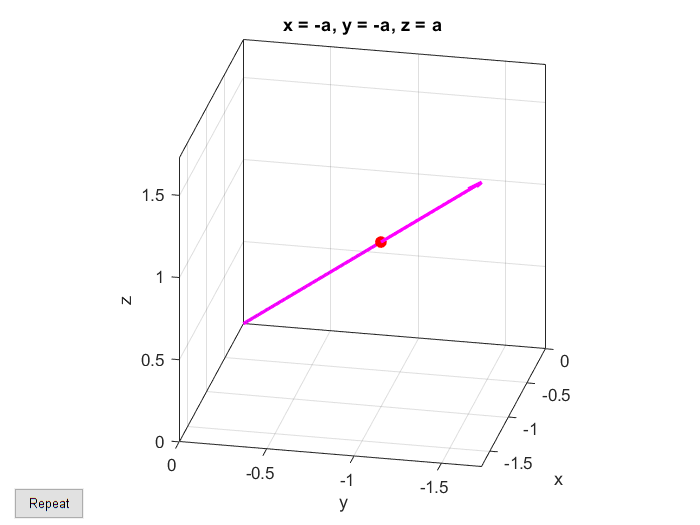

% Visualize the Null space and the left null space
A=[1 0 1;5 4 9;2 4 6];
NA=null(A);

syms a real; r=a*NS;
ezplot3(r(1),r(2),r(3),[0 1],'animate');
axis tight; axis equal; hold on; box on;
h=quiver3(0,0,0,NA(1),NA(2),NA(3),3);
set(h,'Color','m','LineWidth',2);
view(-78,23)

% Column and row space
S=sym([1 0 1;5 4 9;2 4 6]);
RS=colspace(S) % Calculate the row space?

$$RS = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -3 & 1 \end{array}\right)$$

RST=colspace(S')

$$RST = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ 1 & 1 \end{array}\right)$$

Matlab

% Column and row space
A=[1 0 1;5 4 9;2 4 6];
RA=orth(A)

RA =    -0.0915    0.4165
   -0.8279    0.4729
   -0.5533   -0.7765


RAT=orth(A')

RAT =    -0.4012    0.7111
   -0.4153   -0.7030
   -0.8165    0.0081




RA'*RA %The product by these two function is the identical matrix

ans =     1.0000    0.0000
    0.0000    1.0000


% The columns are orthonormal
norm(RA(:,1)) %==1

ans = 1.0000

disp(rref(A))

     1     0     1
     0     1     1
     0     0     0




%----
%The orth function can also be applied to symolic matrix
S=sym([1 0 1;5 4 9;2 4 6]);
RS1=simplify(orth(S))

$$RS1 = \left(\begin{array}{cc} \frac{\sqrt{30}}{30} & -\frac{7\,\sqrt{330}}{330}\\ \frac{\sqrt{30}}{6} & -\frac{\sqrt{330}}{66}\\ \frac{\sqrt{30}}{15} & \frac{8\,\sqrt{330}}{165} \end{array}\right)$$

RS1'*RS1 %Identical matrix

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

Null space and row space

A=[1 0 1;5 4 9;2 4 6];
S=rref(A)

S =      1     0     1
     0     1     1
     0     0     0


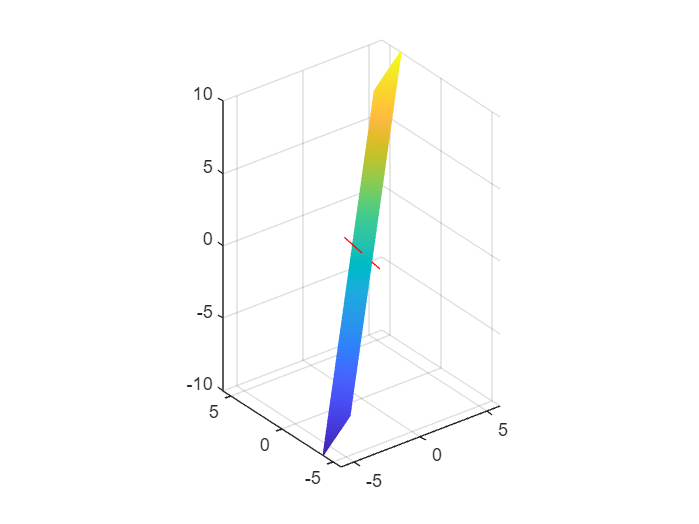

syms a b real; 
p=A([1 2], :)'*[a b]'; %Define p as: Matrix A, first two rows, and then all the columns, and the vector
fmesh(p(1),p(2),p(3),[-1 1]);
axis equal;
N=null(A)*[-10 10];
line(N(1,:),N(2,:),N(3,:),'Color','r') 

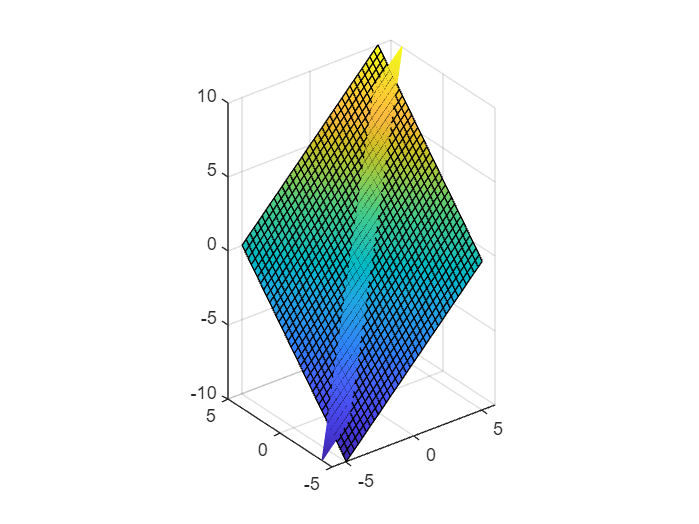

%The vector obtined with the null space is orthogonal to the plane p we
%defined
p=A([1 2],:)'*[a b]';
q=S([1 2],:)'*[a b]';
fmesh(p(1),p(2),p(3),[-1 1])
axis equal; hold on;
fsurf(q(1),q(2),q(3),[-5 5]) 

%The same plane

Left Null space and column space

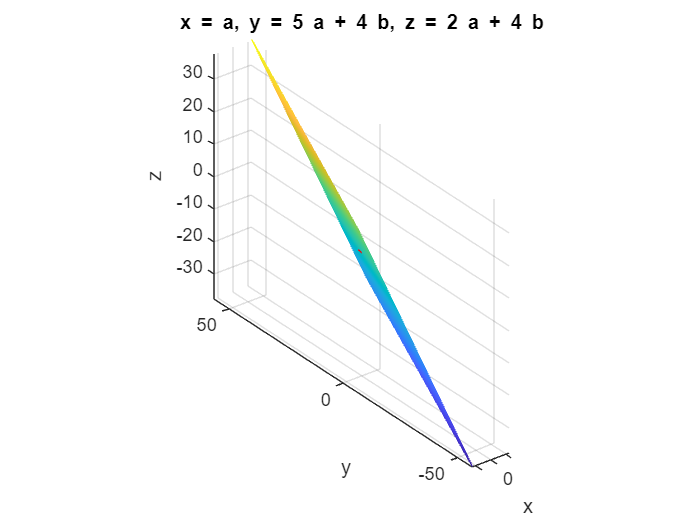

clf;
A=[1 0 1;5 4 9;2 4 6];
S=rref(A);
syms a b real; 
p=A(:,[1 2])*[a b]';
ezmesh(p(1),p(2),p(3))
axis equal; hold on;
line(N(1,:),N(2,:),N(3,:),'Color','r') 

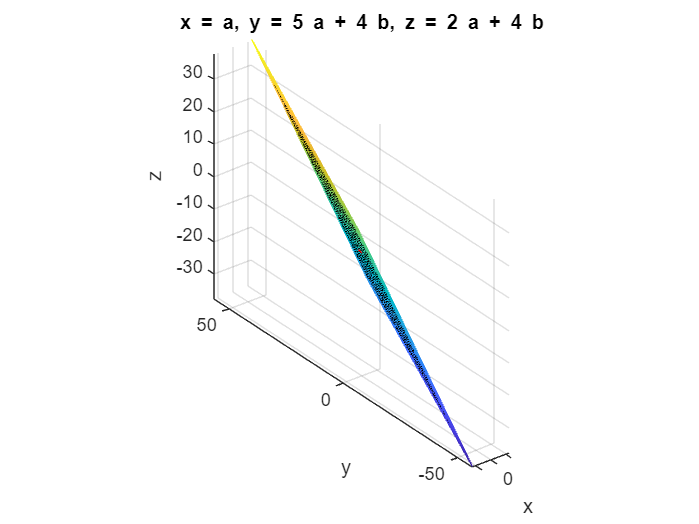


%--------- Ho sbaglito qualcosa qui
p=A(:,[1 2])*[a b]'; 
q=A(:,[1 2])*[a b]';
fmesh(p(1),p(2),p(3));
axis equal; hold on;
fsurf(q(1),q(2),q(3));